y0 = 0.3300

label = 1×6 cell array
    {'phi1'}    {'phi2'}    {'phidot1'}    {'phidot2'}    {'swing'}    {'swingdot'}


isim = 1

IC =     -2
     2
     2
    -1
     0
     0
     0
     1
     0
     0


IC =     -2
     2
     2
    -1
     0
     0
     0
     1
     0
     0


ts = 10000

ans =        49825          10


max =     0.6604         0         0         0
    0.6604         0         0         0
    0.6604         0         0         0
    0.6604         0         0         0


max_swing =     8.7619         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0


ans = 0.0044

FolderName = 'D:\Courses\2-2\SOP\Data\xls_data\N=4\0.330000'

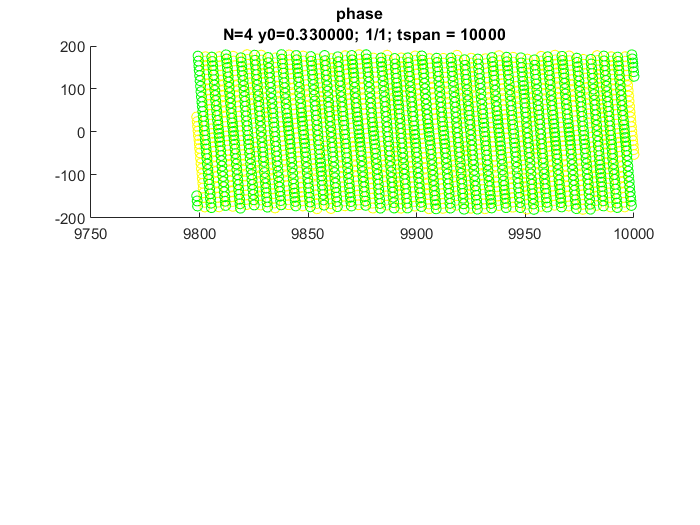

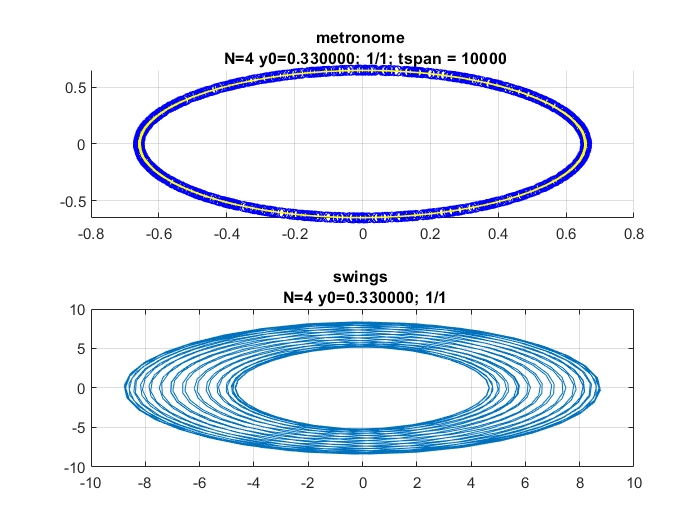

clear
tic ;
% Initial conditions in terms of variable names appearing in the ODE

global N ;
%global Nsim ;
N=4; Nsim=1;

global count;
count = 69;
global y0;
global acc;
acc = [];

for j = 1:1
    y0 = 0.23 + j/10

    
null = {sprintf('COUNT = %d', count)};
label = {'phi1', 'phi2', 'phidot1', 'phidot2', 'swing', 'swingdot'}
% FolderName = sprintf('D:\\Courses\\2-2\\SOP\\Data\\xls_data\\N=%d\\%f', N, y0)
% if ~exist(FolderName, 'dir')
%     mkdir(FolderName)
% end
% FolderName = sprintf('D:\\Courses\\2-2\\SOP\\Data\\xls_data\\N=%d\\%f', N, y0);
% writecell(null, sprintf('%s\\sims.xls', FolderName), 'WriteMode','append');



for isim=1:Nsim % Nsim is no.of simulations each with different init cond
    isim
    %IC = zeros(5,1);
   % IC=[-1.5046 ; 0.6268 ; -0.1304 ; -0.8393 ; -1.0000 ; -2.0000];
    
for i=1:N
   IC(i,1)= 4*(rand(1)-0.5);
%    IC(i,1) = 0;

   IC(i+N,1) = 4*(rand(1)-0.5);
%    IC(i+N, 1) = 0.001
  
   %IC(i,1)= 2*i;
   %IC(i+N,1) = 1/i;
  % IC(i,2) = initial conditions (phi) for metronome on swing-2
  % IC(i+N,2) = initial conditions (phiDOT) for metronome on swing-2
end
IC(2*N+1,1) = 0 ;  % initial condn theta for swing-1
IC(2*N+2,1) = 0 ; % initial condition thetadot for swing-1

% IC(2*N+1,1) = 2*(rand(1)-0.5)
% IC(2*N+2,1) = 2*(rand(1)-0.5)

%IC(2*N+1,2) = initial conditions for swing-2
%IC(2*N+2,2) = 

  
%IC = [ -1.6109 ;-1.8599 ; 1.6338 ;-1.8410 ;-1.0000 ;-2.0000] THis is the
%one that gave oscillation death

% IC = [1.25889474557272; -1.49205273482598; 1.62316774830248; 1.65350342455608; 0.264718492450819; -0.804919190001181]
%^for LAL hugging swing


% IC = [ 1.8300; -1.3695; 1.8596;    1.8824;         0;         0];
%^wtf? both small limit cycle 10^-7

% IC = [-1.5734;   -1.9815;    1.8476;    1.0996;         0;         0];
%^typical SAL

% IC = [1.2589; -1.4921; 1.6232; 1.6535; 0.2647; -0.8049]
% ^SAL

% IC = [0.5; 0.8783; 0.5; 1.9846; 0; 0]

% IC = [1.6; 0.8783; 1.5; 1.9846; 0; 0]
%^both on SAL, oscillation death

% IC = [-1.2638;    0.0039;   -1.0351;    0.0919;   12.3752;    9.0588]

% IC = [0; 1.8; 
%       0; 1.7; 
%       0; 0]

IC = [-2; 2; 2; -1;
      0; 0; 0; 1;
      0; 0]
%^sugar h0ow you get so flyyy sugar how do you get so fly

% IC = [1.7; 1.8; 1.63; 1.77; 1.8; 1.9;
%     1.8; -1.73; 1.71; -1.65; -1.78; 1.73;
%     0; 0]

IC

%time duration of simulation
ts = 10000
tspan = [0 ts]; % in what units ???????
%tspan = [0 500000];
%tspan = [0 1000000];

% Pass on the Initial conditions to a new array called IC. 
% Dimensionality of IC is equal to that of the system of ODEs.
% This array IC will be passed to ode4

% syms t m(t) k(t) Y;
% k(t) = 109*cos(0.7889*t);
% eqns = [diff(diff(m(t), t), t) == -sin(m(t)) - mu_m*diff(m(t),t)((m(t)^2 - 1) - freq_rat_sq*diff(diff(s(t),t),t)];
% [VF, Subs] = odeToVectorField(eqns)
% odefcn = matlabFunction(VF, 'Vars', {t, Y})
% 
% IC = [0];


options = odeset('RelTol', 1.e-3);
% Solve the ODEs
[T,Y] = ode45(@MetronomeSwingEqn,tspan,IC, options);


% Find unique states (limit cycles) & number of metronomes occupying each
% limit cycle
size(Y)

Y(:,1:N) = wrapToPi(Y(:,1:N));

%x = Y(end-1000:end,1:2*N+2);
X = Y(:,1:2*N+2);
%find_ltcyc_algo1_5Aug(x,isim) 
%find_ltcyc_algo1_12Aug(x,isim)
%find_ltcyc_8Aug(x,isim)

color = ['b', 'c', 'r', 'y', 'o', 'g', 'v', 'i', 'b'];
figure1=figure('Name', sprintf('y0 = %f',y0));
for i=1:N
    subplot(2, 1, 1);
    if i ~= 1
        plot(Y(end-1000:end,i),Y(end-1000:end,i+N), color(i));
    end 
    if i == 1
        scatter(Y(end-1000:end,i),Y(end-1000:end,i+N), color(i)); 
    end

    % scatter(Y(end-5:end,i),Y(end-5:end,i+N));
    % scatter(T(end-1000:end, i), Y(end-1000:end,i));
%     xlim([-2 2]);
%     ylim([-2 2]);
    % plot(wrapToPi(Y(:,i)),Y(:,i+N))
    hold on
end
grid on
title(sprintf('metronome \n N=%d y0=%f; %d/%d; tspan = %d', N, y0, isim, Nsim, ts), 'FontSize', 15);

met_pos = Y(:, 1:N);
met_vel = Y(:, N+1:2*N);
met_phase_angle = atan2d(met_vel, met_pos);
met_phase = met_vel./met_pos;
% for i = 1:N
%     for j = 1:N
%         met_phase(i,j) = atan2(met_vel(i, j), met_pos(i,j))
%     end
% end
swing_pos = Y(:, 2*N+1);
swing_vel = Y(:, 2*N+2);
swing_phase_angle = atan2d(swing_vel, swing_pos);
swing_phase = swing_vel./swing_pos;
max = maxdist(met_pos, 1);
max_swing = maxdist(swing_pos, 0);

% cycle = [0 0 0]
% for i = size(swing_phase_angle)-5000:size(swing_phase_angle)
%     for j=1:N
%         if met_phase_angle(i, j)>0 && met_phase_angle(i-1, 1)<0
%     
%             cycle(j) = cycle(j) + 1;
%         
%         end
%         met_phase_angle(i,j) = met_phase_angle(i,j) - cycle(j)*360;
%     end
%     if swing_phase_angle(i)>0 && swing_phase_angle(i-1)<0
%     
%         cycle(N+1) = cycle(N+1) + 1;
%         
%     end
%     swing_phase_angle(i) = swing_phase_angle(i) - cycle(N+1)*360;
% end



figure2=figure('Name', sprintf('phase_of_y0 = %f',y0));
for i=1:N
    subplot(2, 1, 1);
    scatter(T(end-1000:end), met_phase_angle(end-1000:end, i), color(i))
    hold on
end
scatter(T(end-1000:end), swing_phase_angle(end-1000:end), 'g')
title(sprintf('phase \n N=%d y0=%f; %d/%d; tspan = %d', N, y0, isim, Nsim, ts), 'FontSize', 15);

max
max_swing
0.0005*max_swing(1,1)

FolderName = sprintf('D:\\Courses\\2-2\\SOP\\Data\\xls_data\\N=%d\\%f', N, y0)
if ~exist(FolderName, 'dir')
    mkdir(FolderName)
end
% C = {'IC', sprintf('count = %d', count), sprintf('isim = %d/%d', isim, Nsim), sprintf('y0 = %f, N = %d', y0, N)};
% D = {sprintf('%s\\y0 = %f_%d', FolderName, y0, count)};
% writecell(C, sprintf('%s\\sims.xls', FolderName), 'WriteMode','append')
% writematrix(IC, sprintf('%s\\sims.xls', FolderName), 'WriteMode', 'append')
% writecell(label, sprintf('%s\\sims.xls', FolderName), 'WriteMode','append')
writematrix(X, sprintf('%s\\sims.xls', FolderName))
saveas(figure1, fullfile(FolderName, [sprintf('y0 = %f_%s %d-%d',y0, count, isim, Nsim), '..fig']), 'jpg');

subplot(2,1,2);
%plot(wraptopi(Y(end-1000:end,2*N+1)),Y(end-1000:end,2*N+2));
plot(Y(end-1000:end,2*N+1),Y(end-1000:end,2*N+2));
%plot(Y(:,2*N+1),Y(:,2*N+2));
hold on
grid on
title(sprintf('swings \n N=%d y0=%f; %d/%d', N, y0, isim, Nsim), 'FontSize', 15);



end
% FolderName = sprintf('D:\\Courses\\2-2\\SOP\\Data\\N=%d\\%f', N, y0)
% if ~exist(FolderName, 'dir')
%    mkdir(FolderName)
% end
% saveas(figure1, fullfile(FolderName, [sprintf('y0 = %f_%d ',y0, count), '..fig']), 'jpg')
end


%*******plot commands .........




function dydt = MetronomeSwingEqn(t,y)

global N;
%global Nsim ;

%N = 1;
%omega_met = 2;
%omega_swing = 1;
beta = 0.0005;
%beta = 0;
freq_rat_sq = 0.6;
% freq_rat_sq = 0;
cplng= 0.092; % coupling strength of spring between metronomes
cplng = 0;
mu_s = 0.00016;  % damping coefficient for swing

%mu_m = 0.011; %damping for metronome
mu_m = 0.011;
%mu_m = 3;
%y0 = 1;

%y0 = 0.6 ;
global y0;
%freq = (omega_met/omega_swing)^2 ;
%freq1 = 0;
%freq2 = 100;
%cplng = coupling_strength/omega_met^2 ;

dydt = zeros(2*N+2,1);
%dydt = zeros(2*N,1) ; % test : for a single metronome


% y(1,1), y(2,1),....,y(N,1) == phi_metronome (metronome angle on swing-1) 
% y(N+1,1), y(N+2,1), ...,y(2N,1) == phiDOT_metronome (metronome ang speed on swing-1)
% y(2N+1,1) == phi of swing-1
% y(2N+2,1) == phidot of swing-1
% y(1,2),y(2,2),....,y(N,2) == phi_metronome on swing-2
% y(N+1,2),y(N+2,2),....y(2N,2) == phiDOT_metronome on swing-2
% y(2N+1,2) == phi of swing-2
% y(2N+2,2) == phidot of swing-2

% The differential equation

sum1 = 0; sum2=0 ; sum3=0 ;
for j=1:N
    sum1 = sum1 + cos(y(j,1))*cos(y(j,1));
    sum2 = sum2 + y(j+N,1)*y(j+N,1)*sin(y(j,1)); 
    sum3 = sum3 + cos(y(j,1))*( -sin(y(j,1)) - mu_m*( (y(j,1)/y0)^2-1 )*y(j+N,1) );
end
sum1 = -beta*sum1;
sum1 = 1/(1+sum1) ;

% syms t;
% f = @(t) 109*cos(0.7889*t);
% g = @(t) diff(f);
% h = @(t) diff(g);
% CONSTRUCT METRONOME (on swing-1) ODE TERMS
for i=1:N
   dydt(i,1) = y(i+N,1); % theta eqn for metronome-i on swing-1
%    dydt(i+N, 1) =  -sin(y(i,1)) - mu_m*( (y(i,1)/y0)^2-1 )*y(i+N,1);
%    dydt(i+N, 1) = dydt(i+N,1) + beta*cos(y(i,1))*133.7*0.7757*0.7757*cos(0.7757*t);

   %thetadot ODE for metronome-i on swing-1

   dydt(i+N,1) = -sin(y(i,1)) - mu_m*( (y(i,1)/y0)^2-1 )*y(i+N,1); % Just the Van-Der Pol term
   %dydt(i+N,1) = dydt(i+N,1) - beta*cos(y(i,1))*sum1*(sum2 - sum3 ); % Other metronome terms
   dydt(i+N,1) = dydt(i+N,1) - beta*cos(y(i,1))*sum1*(sum2-sum3);
   dydt(i+N,1) = dydt(i+N,1) - beta*cos(y(i,1))*sum1*(-freq_rat_sq*y(2*N+1,1)-mu_s*(y(2*N+2,1))); %swing-1 terms
    %dydt(i+N,1) = dydt(i+N,1) - beta*cos(y(i,1))*sum1*cplng*(y(2*N+1,2)-y(2*N+1,1)); % swing-2 coupling terms

end

% CONSTRUCT SWING-1 ODE TERMS

% dydt(2*N+1,1) = -0*133.7*0.7757*sin(0.7757*t);
% dydt(2*N+2,1) = -0*133.7*0.7757*0.7757*cos(0.7757*t);

dydt(2*N+1,1) = y(2*N+2,1);
dydt(2*N+2,1) = sum1*(- freq_rat_sq*y(2*N+1,1) -mu_s*y(2*N+2,1)); % free swing-1 terms
dydt(2*N+2,1) = dydt(2*N+2,1) + sum1*(-sum3 + sum2); %metronome on swing-1 terms
%dydt(2*N+2,1) = dydt(2*N+2,1) + sum1*cplng*(y(2*N+1,2)-y(2*N+1,1)); %coupling with swing-2 terms

global acc;
acc(end+1, 1) = dydt(2*N+2, 1);

end


function max = maxdist(x, is_met)
    x = x(end-1000:end, :);
    global N
    max = zeros(N);
    if is_met == 1
        for j = 1:N
            for i = 1:1000
                if x(i, j) > max(j)
                    max(j) = x(i,j);
                end
            end
        end
    end 
    if is_met == 0
       for i = 1:1000
           if x(i) > max(1)
               max(1) = x(i);
           end
        end 
    end
end

